1) Calculating Acceleration from Velocity

v = [0, 6, 8, 2, 2, 4, -2];
t = [0, 20, 40, 50, 70, 90, 100];
%homegrown function
dv =  diff(v);
dt = diff(t);
a = dv./dt

a =           0.3          0.1         -0.6            0          0.1         -0.6


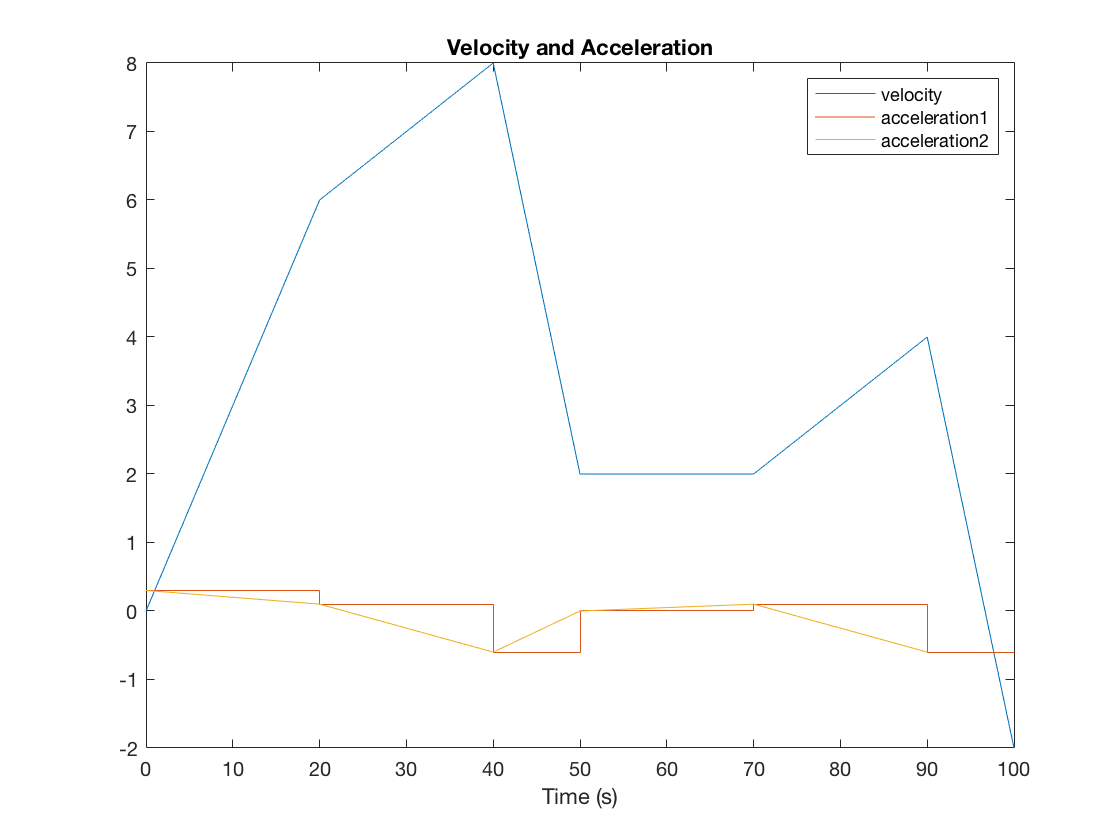

a = [a, a(1, end)];

plot(t, v,'DisplayName', 'velocity')
hold on
stairs(t, a,'DisplayName', 'acceleration1')
legend
title("Velocity and Acceleration")
xlabel("Time (s)")

%built-in function
a = diff(v)./diff(t);
plot(t(1:length(a)), a, 'DisplayName', 'acceleration2')

hold off

Displacement

%homegrown function
h = diff(t);
for i = 1:length(v)-1
    trap(i) = 0.5*(v(i)+v(i+1))*h(i);
end
d = sum(trap)

d =    360


For this function it makes more sense to use the trapezoid method than Simpson's method to calculate the integral because the trapezoid method can exactly integrate a linear function like this one

%built-in function
trapz(t, v)

ans =    360


2 )$f\left(x\right)={\mathrm{sin}}^2 \left(\frac{1}{x\left(2-x\right)}\right)$

a) $\frac{d}{\mathit{dx}}\left(\sin^2 \left(\frac{1}{x\left(2-x\right)}\right)\right)$

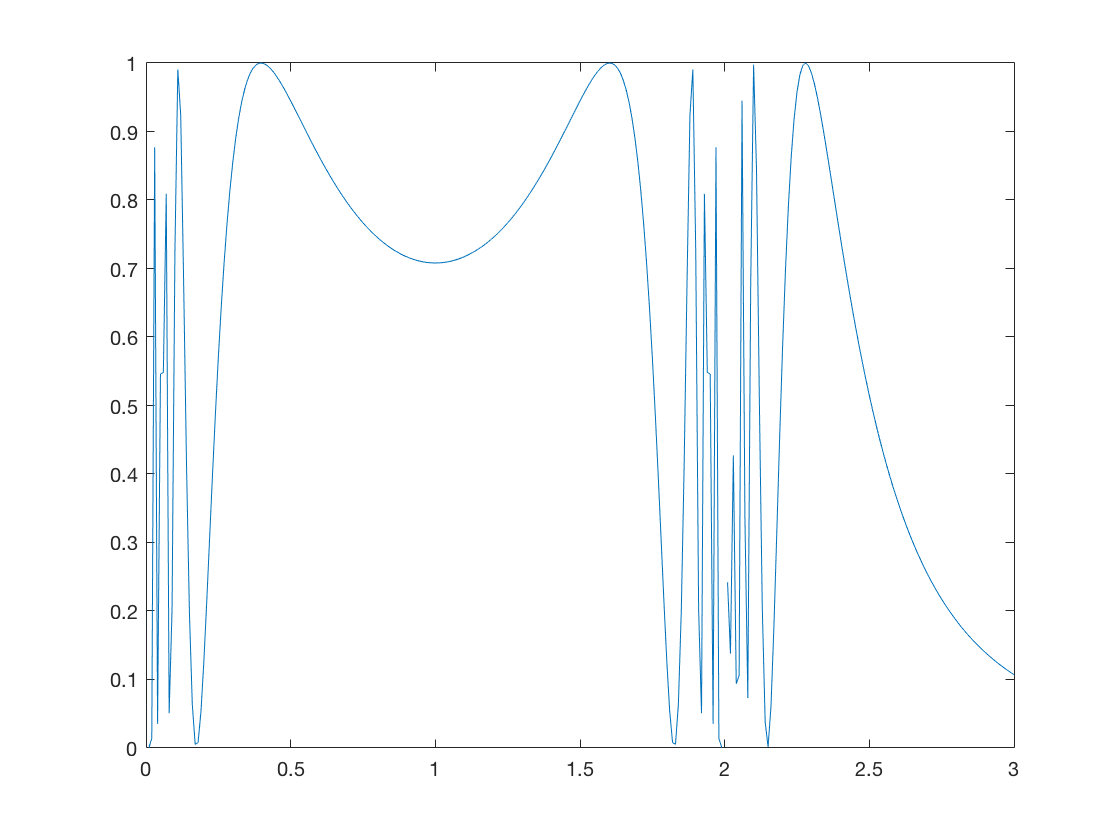

F = @(x) (sin(1./(x.*(2-x)))).^2;
h = 0.01;
j = 0:h:3;
plot(j, F(j))

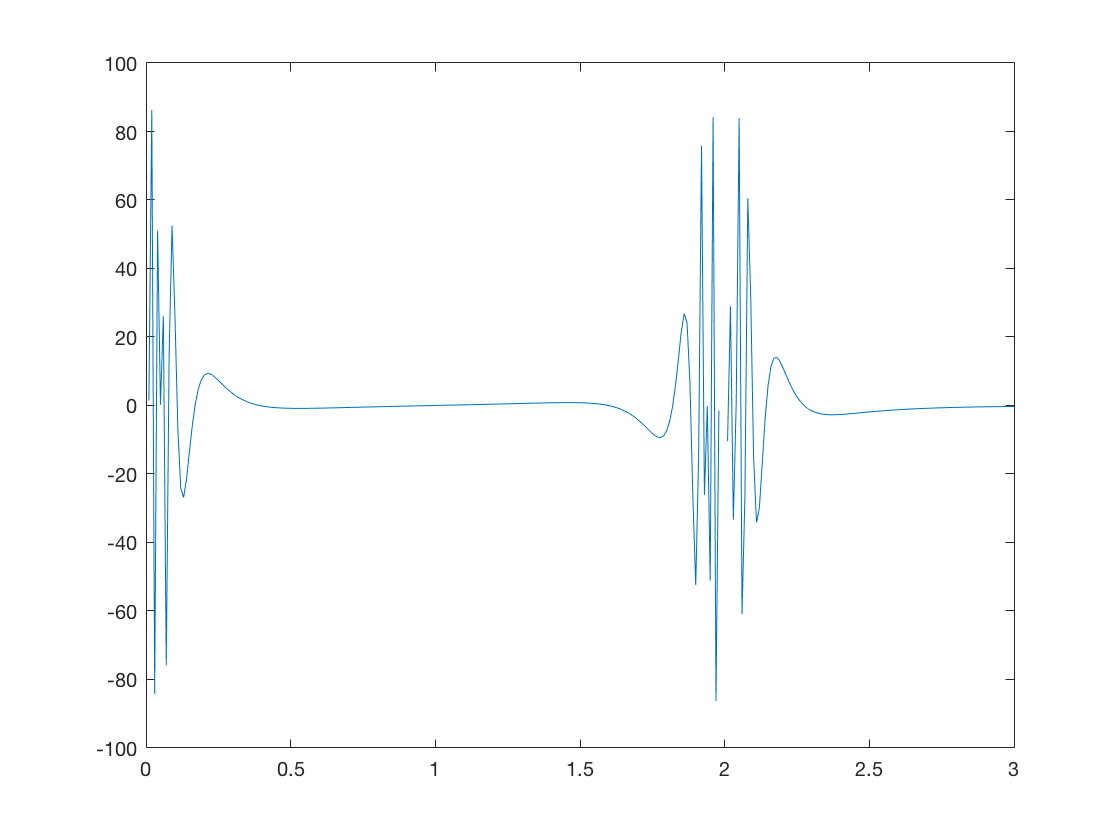

%homegrown derivative
n = 1;
for i = 0:h:3
    dF(n) = (F(i+h)-F(i))/h;
    n = n + 1;
end
plot(j, dF)


%built-in derivative

%{
syms g(y)
g(y) = (sin(1/(y*(2-y))))^2;
b = diff(g, y);
%}

b) $\int_0^2 \sin^2 \left(\frac{1}{x\left(2-x\right)}\right)\mathit{dx}$

%homegrown integral
%trapezoid rule
F = @(x) (sin(1./(x.*(2-x)))).^2;
h = 0.01;
n = 1;
I = 0;
for i = h:h:(2-h)
    I = I + h*F(n*h);
    n = n + 1;
end
Integral1 = I

Integral1 =        1.4272


%error
I2 = 0;
n = 1;
h = h/2;
for i = h:h:(2-h)
    I2 = I2 + h*F(n*h);
    n = n + 1;
end
errorIntegral1 = abs((1/3)*(I2-I))

errorIntegral1 =     0.0063475



%built-in integral
Integral2 = integral(F, 0, 2)

Integral2 =        1.4514


%error

%Romberg method



%{
c = int(g, y)


y=(.001:.001:3);
z = eval(b)
%z = subs(g, y, h)
plot(y, F(y), y, z)
grid on
%{
hold on
axis([0 3 -10 10])
h2 = (.001:.001:2);
u = subs(c,y,h2);
plot(h, u)
%}
%calculate integral
%}


3) Calculating Integrals


$$\int_0^{\pi } \mathrm{sin}\left(x^2 \right)\mathrm{dx}$$


F = @(x) sin(x.^2);
%homegrown function
h = 0.0001;
n = 1;
I = 0;
for i = h:h:(2-h)
    I = I + h*F(n*h);
    n = n + 1;
end
I

I =       0.80481


%error
I2 = 0;
n = 1;
h = h/2;
for i = h:h:(2-h)
    I2 = I2 + h*F(n*h);
    n = n + 1;
end
error = abs((1/3)*(I2-I))

error =    6.3061e-06


%built-in function
F = integral(F, 0, pi)

F =       0.77265


%error

%romberg method



$$\int_0^{\pi } {\mathrm{sin}}^2 \left(x^2 \right)\mathrm{dx}$$


F = @(x) (sin(x.^2)).^2;
%homegrown function
h = 0.01;
n = 1;
I = 0;
for i = h:h:(pi-h)
    I = I + h*F(n*h);
    n = n + 1;
end
I

I =        1.3179


%error
I2 = 0;
n = 1;
h = h/2;
for i = h:h:(pi-h)
    I2 = I2 + h*F(n*h);
    n = n + 1;
end
error = abs((1/3)*(I2-I))

error =    0.00013788


%built-in function
I1 = integral(F, 0, pi)

I1 =         1.319


%romberg method


$$\int_1^{e^{\pi /2} } \cos \left(\mathrm{ln}\left(x\right)\right)\textrm{dx}$$


G = @(x) cos(log(x));
%homegrown function
h = 0.01;
n = 1;
I = 0;
for i = 1:h:(exp(pi/2))
    I = I + h*G(1+n*h);
    n = n + 1;
end
I

I =        1.9002


%error
I2 = 0;
n = 1;
h = h/2;
for i = 1:h:(exp(pi/2))
    I2 = I2 + h*G(n*h);
    n = n + 1;
end
error = abs((1/3)*(I2-I))

error =       0.13113


%built-in function
I1 = integral(G, 1, exp(pi/2))

I1 =        1.9052


 
$$\int_1^{2\pi } \frac{\mathrm{sin}\left(x\right)}{\mathrm{ln}\left(x\right)}\textrm{dx}$$


F = @(x) sin(x)./log(x);
%homegrown function
h = 0.00001;
n = 1;
I = 0;
for i = 1:h:(2*pi)
    I = I + h*F(1+n*h);
    n = n + 1;
end
I

I =        10.302


%error
I2 = 0;
n = 1;
h = h/2;
for i = 1:h:2*pi
    I2 = I2 + h*F(1+n*h);
    n = n + 1;
end
error = abs((1/3)*(I2-I))

error =       0.19442


%built-in function
I1 = integral(F, 1, 2*pi)

I1 =        32.219


%romberg method